# Dynamics Simulation 

Dynamic Simulation for the 2 DoF Space Robot

clc
load 'SR2.mat'

sr.homeConfig();
q_0 = sr.q;
q_dot_0 = sr.q_dot;

Parameters

fileName = '';          % Where to save animation, Do not save if left as ''
animationTEnd = 10;     % When to stop animation time

simTime = '10.0';       % Simulation end time

% Forces
fx = 1;
fy = 0;
fz = 0;s

nx = 0;
ny = 0;
nz = 0;

tau1 = 0;
tau2 = 0;
tau = [tau1; tau2];

f = 0.5;
dt = 1

dt = 1

### Launch Simulation

% profile on
tic
set_param('open_loop_dyn', 'StopTime', simTime)
simRes = sim('open_loop_dyn');
toc

Elapsed time is 1.327587 seconds.


% profile viewer
% profile off

### Animate Results

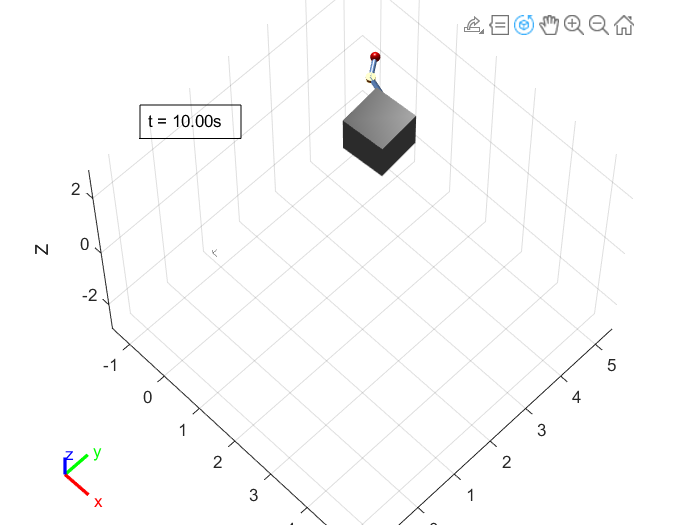

clc
close all
folder = 'Project/Videos/';

data = simRes.q.getsampleusingtime(0, animationTEnd);

if ~strcmp(fileName, '')
    savePath = strcat(folder, fileName);
else
    savePath = '';
end

tic
sr.animate(data, 'fps', 17, 'rate', 1, 'fileName', savePath); 

toc

Elapsed time is 11.703913 seconds.
